# Transfer Learning with Medical Images

This example shows how transfer learning for image classification can be achieved for a variety of datasets.  

clear;close all;clc;

## Configure Example Options

imdir = 's3://bmedatasets/chestxrays/chest_xray';
numWorkers = 4;
delete(gcp('nocreate'))

## Task 1:  Access the dataset and prepare for deep learning

Use `imageDatastore` to access your images.  `imageDatastore` is an example of a `datastore` in MATLAB, which is a container that points to data and controls how that data is brought into MATLAB.  It is an object that has properties to describe it, and methods that can be performed on it.  

imdir

imdir = 's3://bmedatasets/2DImageSet_20200228T104037'

imdir = fullfile(toolboxdir('nnet'),'nndemos','nndatasets','DigitDataset');
imgSet = imageDatastore(imdir,...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames')

imgSet =   ImageDatastore with properties:

                       Files: {
                              ' ...\R2022a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image10000.png';
                              ' ...\R2022a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9001.png';
                              ' ...\R2022a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9002.png'
                               ... and 9997 more
                              }
                     Folders: {
                              ' ...\MATLAB\R2022a\toolbox\nnet\nndemos\nndatasets\DigitDataset'
                              }
                      Labels: [0; 0; 0 ... and 9997 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFc

Use the `datastore` properties to view the dataset at a high level.

labelCount = countEachLabel(imgSet);
bar(labelCount.Label,labelCount.Count);
title('Class Labels')

### **What do these images look like?**

Let's take a quick look at what the different image classes look like.  

subset = splitEachLabel(imgSet,3,'randomized');
imgs = readall(subset);
montage(imgs,'Size',[height(labelCount) 3])
ylabel(join(string(flipud(labelCount.Label)),"     |     "),...
    'FontWeight','bold')

## Task 2: Prototype and develop a deep learning model

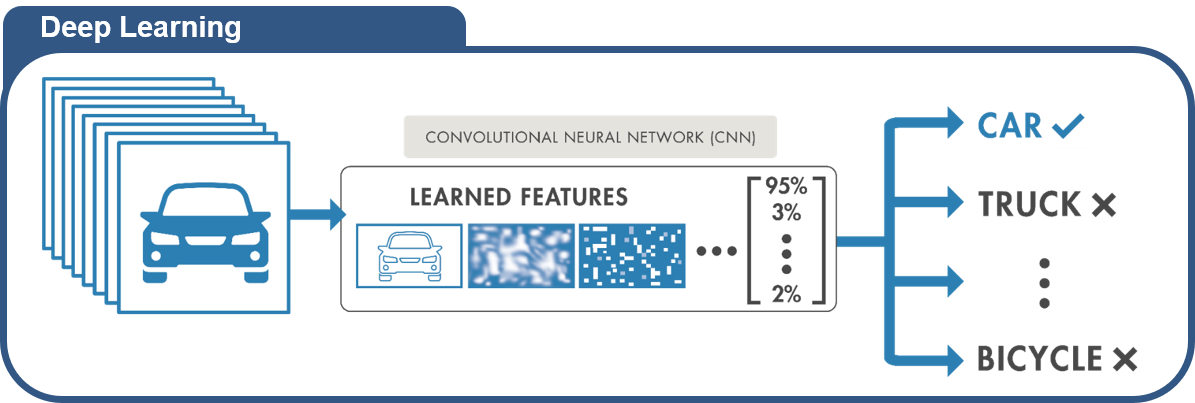

Run this section and click the link below to skip the deep learning set up for training.

DLSetUp

SkipDeepLearningSetUp

### **Partitioning the training and testing sets**

Let's use one of the image datastore methods to randomly divide the dataset into training and test sets. 

[imgSet_balanced] = splitEachLabel(imgSet,min(labelCount.Count));
[trainSets,valSets,testSets] = splitEachLabel(imgSet_balanced,0.5, 0.3, 0.2,'randomized');
trainLabelCount = countEachLabel(trainSets);
valLabelCount = countEachLabel(valSets);
testLabelCount = countEachLabel(testSets);

figure
bar(trainLabelCount.Label,[trainLabelCount.Count,valLabelCount.Count,testLabelCount.Count]);
title('Partitioned Dataset')
legend('Training Set','Validation Set','Testing Set')

### Transfer Learning

In this example, we will perform transfer learning off of an existing trained neural network.  MATLAB provides implementations of several published trained networks, as well as supports network importing through the ONNX format.

net = resnet18

We can explore the network using the Analyze Network App:

Let's take a closer look at the first layer:

net.Layers(1)
net.Layers(end)

### Preparing the network for transfer learning

Right now, the network is set up to classify all inputs as one of 1,000 categories.  We would like it to classify our dataset's classes.  To do this, we need to modify the final layers of the network to give us the desired number of outputs.  This can be accomplished to the Deep Network Designer App...

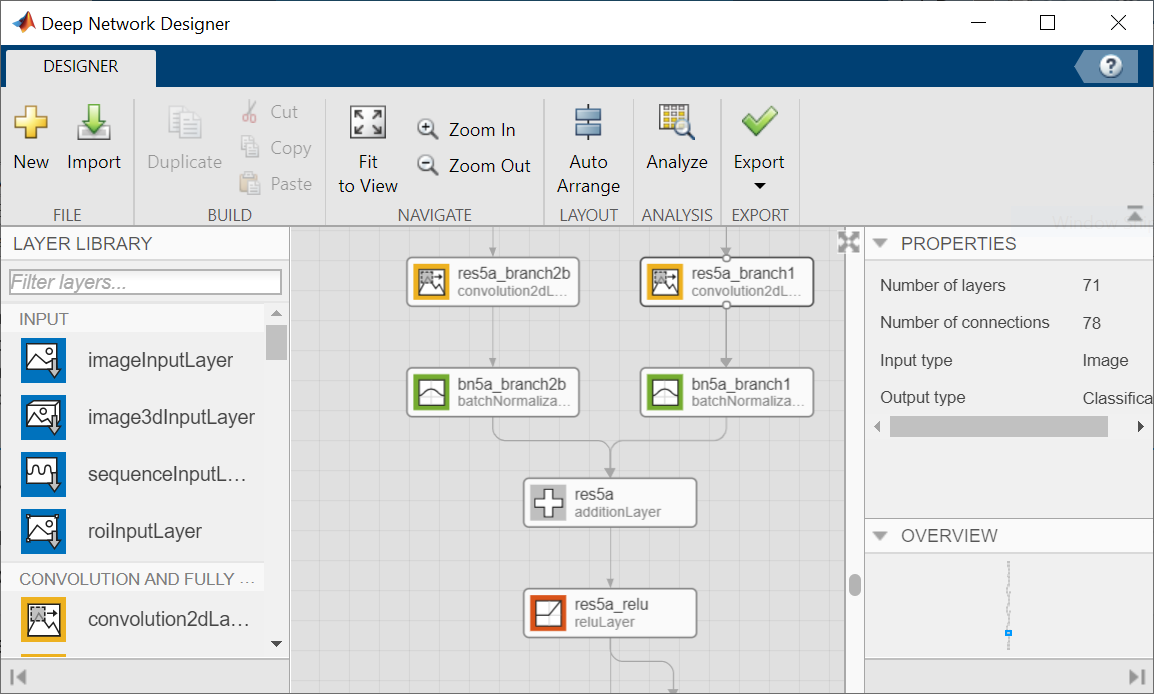

... Or programmitically.

lgraph = layerGraph(net);

% Turn off normalization to save training time
newinputlayer = imageInputLayer(lgraph.Layers(1).InputSize,'Normalization','none','Name','Data');
lgraph = replaceLayer(lgraph,lgraph.Layers(1).Name,newinputlayer);

numclasses = numel(unique(imgSet.Labels));
newfullyconnectedlayer = fullyConnectedLayer(numclasses,'Name','myFullyConnectedLayer');
lgraph = replaceLayer(lgraph,lgraph.Layers(end-2).Name,newfullyconnectedlayer);

newclassificationlayer = classificationLayer('Name','myClassificationLayer');
lgraph = replaceLayer(lgraph,lgraph.Layers(end).Name,newclassificationlayer);

We can note that this network is set up to accept images of a specific size. Our raw images are not of that size and will need to be resized before being sent into the network:

size(preview(imgSet))

In order for the network to accept out images, they must first be resized.  So we see there is an image resize step in order to properly perform classification with this network.  This can easily be applied by indicating through the image datastore's `ReadFcn` that the image must be resized.  Let's define a read function to properly size our images for the neural network:

type("myImgImportFcn.m")
inputSize = net.Layers(1).InputSize(1:2);
readfcn = @(x) myImgImportFcn(x,inputSize);
imgSet.ReadFcn = readfcn;
trainSet.ReadFcn = readfcn;
testSet.ReadFcn = readfcn;
valSet.ReadFcn = readfcn;

Now let's see the neural network in action.  When `methods(net)` is called on the neural network, we get a list of functions that are defined for neural networks.  Among them is the function `classify` which we can use for predicting the class of an input image.

tempimg = readimage(imgSet,randi(numel(imgSet.Files)));
classify(net,tempimg)
imshow(tempimg)

### Augmenting our dataset

It sometimes benefits training if we augment the data through a variety of methods such as reflection, rotation, etc.  This will help us prevent overfitting.

augmenter = imageDataAugmenter('RandXReflection',true,...
    'RandXTranslation', [-10 10],...
    'RandYTranslation',[-10 10],...
    'RandRotation',[0 180])
augimds = augmentedImageDatastore(lgraph.Layers(1).InputSize,trainSets,'DataAugmentation',augmenter)

### Train the Neural Network

Now that we have prepped our data and modified the neural network, we are ready to train!

options = trainingOptions('sgdm',...
    'InitialLearnRate',  0.001, ...
    'ValidationData',valSets,...
    'ValidationPatience',5,...
    'Plots', 'training-progress',...
    'ExecutionEnvironment','parallel')

runMode = "inProcess";
switch runMode
    case "inProcess"
        p = parpool(numWorkers,...
            'AttachedFiles','myImgImportFcn.m',...
            'EnvironmentVariables',{'AWS_ACCESS_KEY_ID','AWS_SECRET_ACCESS_KEY','AWS_SESSION_TOKEN'});
        myNet = trainNetwork(augimds, lgraph, options);
    case "batch"
        delete(gcp('nocreate'))
        job = batch(@trainNetwork, 1, {augimds, lgraph, options},...
            'Pool',3,...
            'AttachedFiles','myImgImportFcn.m',...
            'EnvironmentVariables',{'AWS_ACCESS_KEY_ID','AWS_SECRET_ACCESS_KEY','AWS_SESSION_TOKEN'});

To access and check up on the state of the job, use `diary` or `State`.  Once the job is done, retrieve the results with `fetchOutputs`.

        s = load(presavedmat);
        myNet = s.trainedNet;
    case "load_existing"
        s = load(presavedmat);
        myNet = s.trainedNet;
end

### Test the Trained Neural Network

How well does the trained neural network perform against the test dataset?

testSets
predictedLabels = classify(myNet, testSets);
accuracy = mean(predictedLabels == testSets.Labels)
confusionchart(testSets.Labels,predictedLabels,'RowSummary',"row-normalized");
title('Confusion Matrix')

## Task 3:  Inference with the trained network

Let's try out our network against some random images from our test set.

imidx = randi(numel(testSets.Files));
img = readimage(testSets,imidx);
expLabel = testSets.Labels(imidx);
predLabel = classify(myNet,img);
if expLabel == predLabel
    rightwrong = 'g';
else
    rightwrong = 'r';
end
imshow(img)
title("Actual: "+string(expLabel)+"; Predicted: "+string(predLabel),'Color',rightwrong)

### Occlusion Sensitivity

What parts of the image are being activated for each classification?

figure("Position",[10 10 1000 1000])
tl = tiledlayout('flow');
subset = splitEachLabel(testSets,6,'randomized');
for ii = 1:numel(subset.Files)
    img = readimage(subset,ii);
    expLabel = subset.Labels(ii);
    [predLabel, score] = classify(myNet,img);
    
    if expLabel == predLabel
        rightwrong = 'g';
    else
        rightwrong = 'r';
    end
    
    scoreMap = occlusionSensitivity(myNet, img, predLabel);
    
    nexttile
    imshow(img)
    hold on
    imagesc(scoreMap,'AlphaData',0.5)
    hold off
    title({"Actual: "+string(expLabel),"Predicted: "+string(predLabel)},'Color',rightwrong,'FontSize',8)
    xlabel("Score: "+num2str(max(score)))
end

## Improving the Model

How can we improve our model?

### Get/Generate More Data

This is a tricky situation.  Sometimes it's quick and easy to collect more data, sometimes it's difficult and expensive.

#### Generative Adversarial Networks

### Try Different Neural Network Architectures

What if we rerun our code with a different network starting point?

### Hyperparameter Tuning

Let's try different training options to imporve the model.

*Copyright © 2021 MathWorks, Inc.*